n = 32;
h =2/n;
x = linspace(-1, 1, n);% 生成等距节点
x = x';
x = h^2*x.^2;
x(1) = -1;
x(n) = h;
b = x;
fprintf('b的转置为');

b的转置为

disp(b')

   -1.0000    0.0034    0.0030    0.0025    0.0022    0.0018    0.0015    0.0012    0.0009    0.0007    0.0005    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0012    0.0015    0.0018    0.0022    0.0025    0.0030    0.0034    0.0625



A = zeros(n, n);% 初始化 n*n 阶系数矩阵
A(1, 1) = 1;% 设置第一行和最后一行
A(n, n-1) = -1;
A(n, n) = h + 1;
for i = 2:n-1% 设置主对角线及其左右元素
    A(i, i-1) = 1 + 0.5 * n^2 * h;
    A(i, i) = -2 - n * h^2;
    A(i, i+1) = 1 - 0.5 * n^2 * h;
end
fprintf('A为');

A为

disp(A);

    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   33.0000   -2.1250  -31.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   33.0000   -2.1250  -31.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   33.0000   -2.1

u = A\b;
fprintf('数值解向量的转置为');

数值解向量的转置为

disp(u');

   -1.0000   -0.9814   -0.9974   -0.9765   -0.9948   -0.9714   -0.9925   -0.9660   -0.9903   -0.9605   -0.9884   -0.9547   -0.9868   -0.9487   -0.9854   -0.9424   -0.9844   -0.9357   -0.9837   -0.9286   -0.9835   -0.9211   -0.9839   -0.9131   -0.9848   -0.9046   -0.9864   -0.8954   -0.9887   -0.8855   -0.9919   -0.8747



ode = @(x, y) [y(2); x^2 + n^2*y(2) + n*y(1)];% 定义微分方程
%@(x, y)是一个匿名函数，它接受两个参数：x和y。
% y是一个向量，它的第一个元素y(1)表示函数u(x)的值，第二个元素y(2)表示函数u'(x)的值。
% [y(2); x^2 + n^2*y(2) + n*y(1)]是微分方程的右侧，它返回一个向量，向量的第一个元素是u'(x)，第二个元素是u''(x)。

bc = @(ya, yb) [ya(1) + 1; yb(1) + yb(2) - 1];% 定义边界条件
%@(ya, yb)是一个匿名函数，它接受两个参数：ya和yb。
% ya是一个向量，它的元素是在x=-1时u(x)和u'(x)的值。
% yb是一个向量，它的元素是在x=1时u(x)和u'(x)的值。
% [ya(1) + 1; yb(1) + yb(2) - 1]是边界条件的表达式，它返回一个向量，向量的第一个元素是在x=-1时的边界条件，第二个元素是在x=1时的边界条件。

solinit = bvpinit(linspace(-1, 1, 32), [0 0]);% 定义初始猜测,[0 0]是u(x)和u'(x)在每个x值处的初始猜测。

sol = bvp4c(ode, bc, solinit);% 求解微分方程
%bvp4c函数接受三个参数：微分方程ode，边界条件bc，和初始猜测solinit。它返回一个结构体sol，这个结构体包含了求解微分方程的结果。

%这几行画出了求解微分方程的结果。linspace(-1, 1, 32)生成了一个从-1到1的等差数列，它的长度是32。
% deval(sol, x)使用sol中的结果在每个x值处计算u(x)的值。plot(x, y(1,:))画出了u(x)随着x变化的图像。
x = linspace(-1, 1, n);
y = deval(sol, x);

fprintf('精确解向量的转置为');

精确解向量的转置为

disp(y(1,:));

   -1.0000   -0.9980   -0.9961   -0.9941   -0.9922   -0.9902   -0.9882   -0.9863   -0.9843   -0.9823   -0.9803   -0.9784   -0.9764   -0.9744   -0.9725   -0.9705   -0.9686   -0.9666   -0.9647   -0.9627   -0.9608   -0.9589   -0.9570   -0.9550   -0.9531   -0.9512   -0.9493   -0.9475   -0.9456   -0.9437   -0.9419   -0.9382



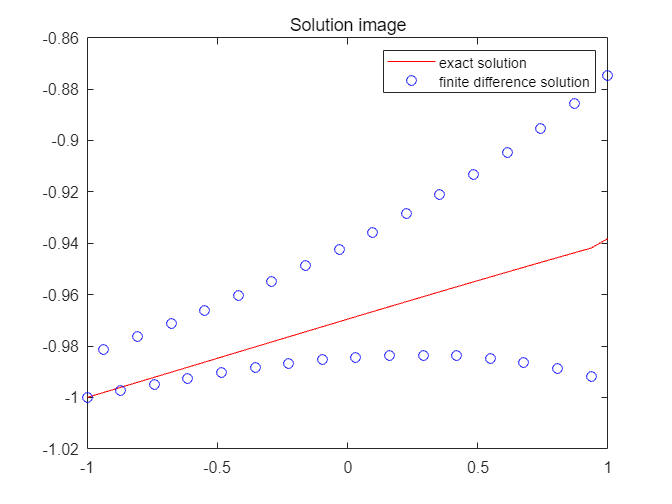

% 画出解的图像
plot(x, y(1,:),'red')
hold on;
plot(x,u,'bo');
hold off;
legend('exact solution', 'finite difference solution');
title("Solution image");

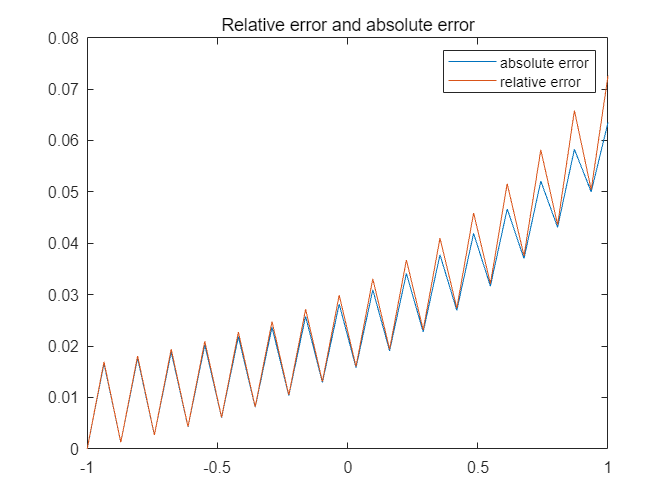


%误差分析
y =y(1,:)';
ab_err = y-u;
plot(x,abs(ab_err));
hold on;
relative_err = abs(ab_err./u);
plot(x,relative_err);
hold off;
legend('absolute error', 'relative error');
title("Relative error and absolute error");

b=djp(n-1,0,0,0);
b=b';
b(1) = -1;
b(32) =1 

b =    -1.0000
   -0.9856
   -0.9648
   -0.9349
   -0.8963
   -0.8494
   -0.7945
   -0.7322
   -0.6630
   -0.5877


x_l = b;
diff_adjacent = diff(b);% 计算相邻两点之间的差值
diff_interval = b(3:end) - b(1:end-2);% 计算间隔一点的差值
%提取间隔的前节点和后节点，用于构造线性组合系数
h_1 = diff_adjacent(1:end-1);
h_2 = diff_adjacent(2:end);
% 计算向量A和向量B,即线性组合系数
A = 2 ./ (h_1 .* (h_1 + h_2))

A = 1.0e+03 *

    3.9446
    1.8918
    0.9788
    0.6060
    0.4183
    0.3110
    0.2442
    0.2002
    0.1700
    0.1488


B = 2 ./ (h_2 .* (h_1 + h_2))

B = 1.0e+03 *

    2.7223
    1.3211
    0.7573
    0.4980
    0.3578
    0.2739
    0.2201
    0.1838
    0.1585
    0.1405


%构造微分微分矩阵
D_1 = zeros(32);% 初始化一个32*32的零矩阵
for i = 2:31% 从第二行开始，每一行的元素只有三个相邻的元素
   D_1(i, i-1:i+1) = [-1/(diff_interval(i-1)), 0, 1/(diff_interval(i-1))];
end
D_1

D_1 =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -28.3787         0   28.3787         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  -19.7218         0   19.7218         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0  -14.6111 

D_2 = zeros(32);% 初始化一个32*32的零矩阵
for i = 2:31% 从第二行开始，每一行的元素只有三个相邻的元素
    D_2(i, i-1:i+1) = [A(i-1), -A(i-1)-B(i-1), B(i-1)];
end
D_2

D_2 = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.9446   -6.6669    2.7223         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.8918   -3.2130    1.3211         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0

I = eye(32);% 构造一个32*32的单位矩阵
A = D_2-(n^2).*D_1-n.*I;
b = b.^2;
%接下来构造边值条件
%迪利克雷边界条件
A(1,1) = 1;
b(1) = -1;
%第三类边界条件
C_1 = -1/diff_adjacent(31)-1/diff_adjacent(30)

C_1 = -117.4633

C_2 = diff_adjacent(31)/((diff_adjacent(30))*(diff_adjacent(30)+diff_adjacent(31)))

C_2 = 19.5847

A(32,30) = C_2;
A(32,31) = C_1;
A(32,32) = -C_1-C_2+1

A = 1.0e+04 *

    0.0001         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.3004   -0.6699   -2.6337         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    2.2087   -0.3245   -1.8874         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0  

b(n) = 1

b =    -1.0000
    0.9714
    0.9308
    0.8740
    0.8034
    0.7214
    0.6312
    0.5361
    0.4396
    0.3454


u = A\b

u =    -1.0000
   -0.9980
   -0.9993
   -0.9962
   -0.9975
   -0.9933
   -0.9947
   -0.9895
   -0.9909
   -0.9849


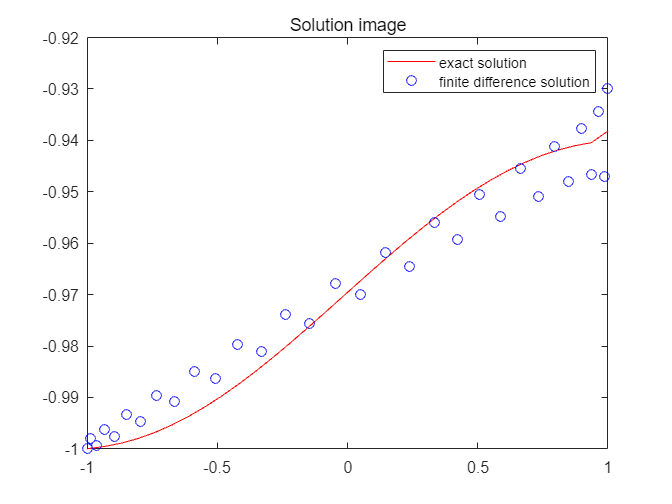


solinit = bvpinit(x_l, [0 0]);% 定义初始猜测,[0 0]是u(x)和u'(x)在每个x值处的初始猜测。

sol = bvp4c(ode, bc, solinit);% 求解微分方程
%bvp4c函数接受三个参数：微分方程ode，边界条件bc，和初始猜测solinit。它返回一个结构体sol，这个结构体包含了求解微分方程的结果。
y_l = deval(sol, x_l);
y = y_l(1,:)';

% 画出解的图像
plot(x, y,'red')
hold on;
plot(x_l,u,'bo');
hold off;
legend('exact solution', 'finite difference solution');
title("Solution image");

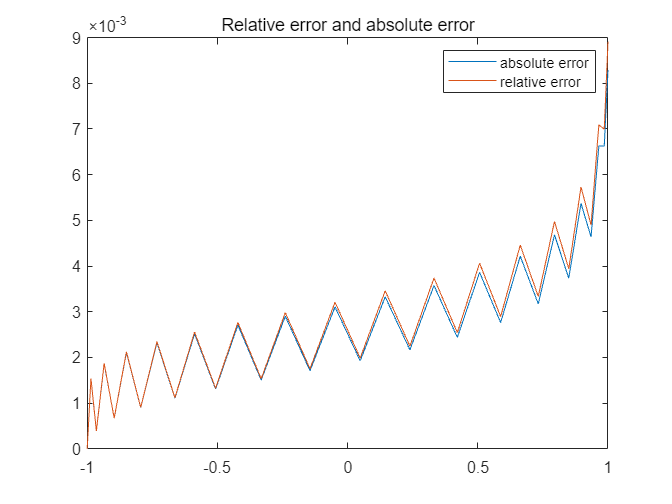


%误差分析
ab_err = y-u;
plot(x_l,abs(ab_err));
hold on;
relative_err = abs(ab_err./u);
plot(x_l,relative_err);
hold off;
legend('absolute error', 'relative error');
title("Relative error and absolute error");


% 函数djp计算m阶导数的勒让德多项式的零点
% 输入参数：
% N - 勒让德多项式的阶数
% alpha, beta - 勒让德多项式的参数，通常取0
% m - 导数的阶数
% 输出参数：
% x - m阶导数的勒让德多项式的零点

function x=djp(N,alpha,beta,m)
    % 计算新的参数值
    N1=N-m;
    alpha1=alpha+m;
    beta1=beta+m;
    % 调用jp函数计算零点
    x=jp(N1,alpha1,beta1);
end

% 函数jp计算勒让德多项式的零点
% 输入参数：
% N - 勒让德多项式的阶数
% alpha, beta - 勒让德多项式的参数
% 输出参数：
% x - 勒让德多项式的零点
function x=jp(N,alpha,beta)
    % 初始化向量n
    n=1:N;
    % 计算系数a和b
    a(1)=(alpha+beta+2)/2;
    b(1)=(beta-alpha)/2;
    a([2:N+1])=(2*n+alpha+beta+1).*(2*n+alpha+beta+2)./(2*(n+1).*(n+alpha+beta+1));
    b([2:N+1])=(alpha*alpha-beta*beta)*(2*n+alpha+beta+1)./(2*(n+1).*(n+alpha+beta+1).*(2*n+alpha+beta));
    % 计算系数c
    c=(n+alpha).*(n+beta).*(2*n+alpha+beta+2)./((n+1).*(n+alpha+beta+1).*(2*n+alpha+beta));
    % 构造矩阵A
    A=diag(b./a)+diag(1./a([1:N]),1)+diag(c./a([2:N+1]),-1);
    % 计算矩阵A的特征值，并排序
    x=sort(eig(A))';
end
